Неподвижные точки

syms u r
r_min = 0; r_max = 3*sqrt(3)/2;
R = [r_min r_max];
answ = solve (u == r*sqrt(u)*(1-u), u);

syms stat_p1(r) stat_p2(r)
stat_p1 = answ(2)

$$stat\_p1 = \frac{{\left(\sqrt{4\,r^{2}+1}-1\right)}^{2}}{4\,r^{2}}$$

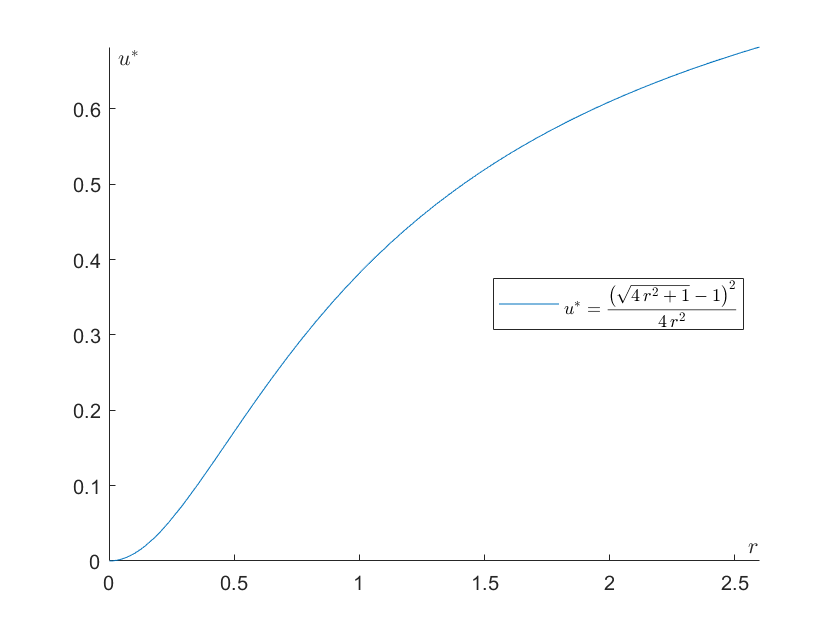

fplot(stat_p1,R); hold on;
plotstyle1('$r$','$u^*$',['$$ u^* = ' latex(stat_p1) '$$'],'east');
hold off;
exportgraphics(gcf,'pictures\ds2_stp.pdf');

График первой неподвижной точки

stat_p2 = answ(3)

$$stat\_p2 = \frac{{\left(\sqrt{4\,r^{2}+1}+1\right)}^{2}}{4\,r^{2}}$$

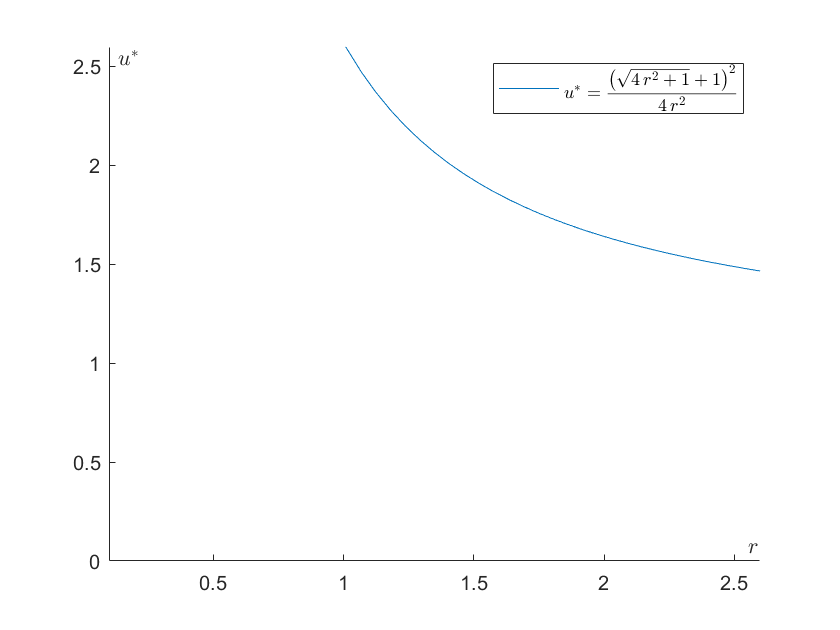

fplot(stat_p2,[0.1 r_max]); hold on;
ax = gca; ax.YLim = R;
plotstyle1('$r$','$u^*$',['$$ u^* = ' latex(stat_p2) '$$'],'northeast');
hold off;

График второй неподвижной точки

Собственные значения

syms r u
r_min = 0; r_max = 3*sqrt(3)/2;
R = [r_min r_max];
j12 = -(sqrt(4*r^2 + 1)-1)^2/(4*r);
J = [1/2 j12; 1 0]

$$J = \left(\begin{array}{cc} \frac{1}{2} & -\frac{{\left(\sqrt{4\,r^{2}+1}-1\right)}^{2}}{4\,r}\\ 1 & 0 \end{array}\right)$$

lambda = eig(J)

$$lambda = \left(\begin{array}{c} \frac{1}{4}-\frac{\sqrt{\frac{r-16\,r^{2}+8\,\sqrt{4\,r^{2}+1}-8}{4\,r}}}{2}\\ \frac{\sqrt{\frac{r-16\,r^{2}+8\,\sqrt{4\,r^{2}+1}-8}{4\,r}}}{2}+\frac{1}{4} \end{array}\right)$$

Первый мультипликатор

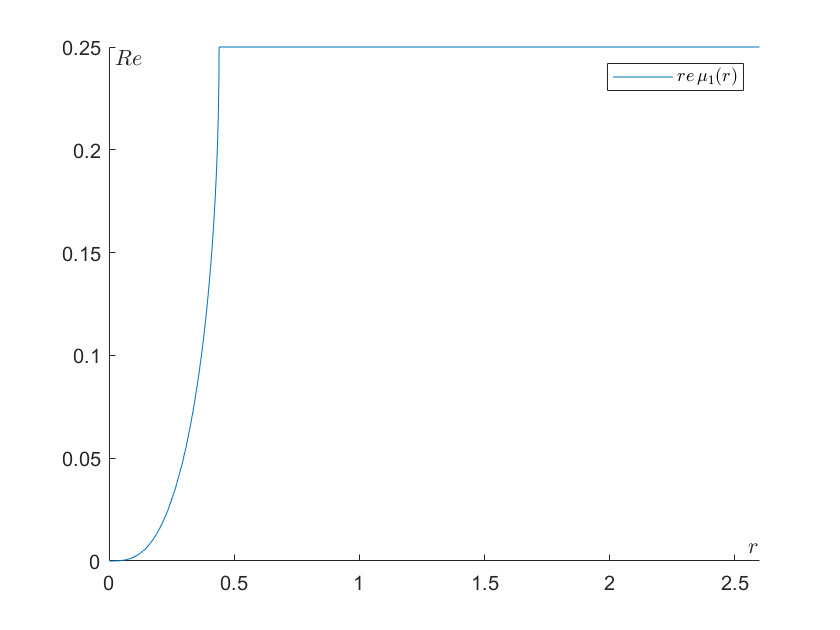

mu_1 = lambda(1);

fplot(real(mu_1),R); hold on;
plotstyle1('$r$','$Re$','$re\,\mu_1(r)$','northeast');
hold off;
exportgraphics(gcf,'pictures\ds2_mu1_re.pdf');

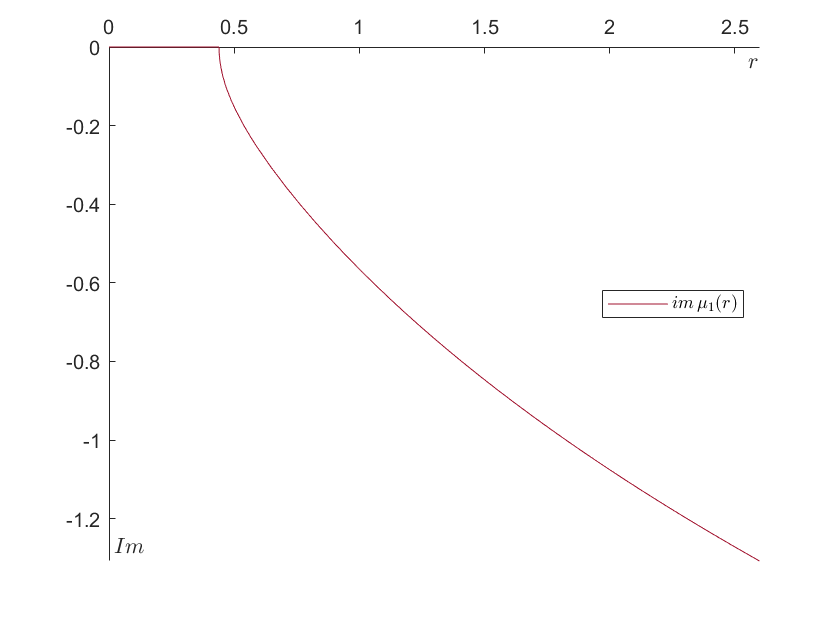


fplot(imag(mu_1),R,'Color','#A2142F'); hold on;
plotstyle1('$r$','$Im$','$ im\,\mu_1(r) $','east');
ax = gca; 
ax.YLabel.Position(2) = ax.YLim(1);
ax.XLabel.Position(2) = ax.YLim(2) - 0.075;
hold off;
exportgraphics(gcf,'pictures\ds2_mu1_im.pdf');

solve(abs(mu_1)== 1, r) %не решается символьно

$$ans = -2.3064439323587723772036249693149$$

num_mu_1 = matlabFunction(mu_1);
r1_0 = fminbnd(@(r) (abs(num_mu_1(r))-1)^2, 0,r_max) %точка перехода модуля собственного значения через 1

r1_0 = 1.7549

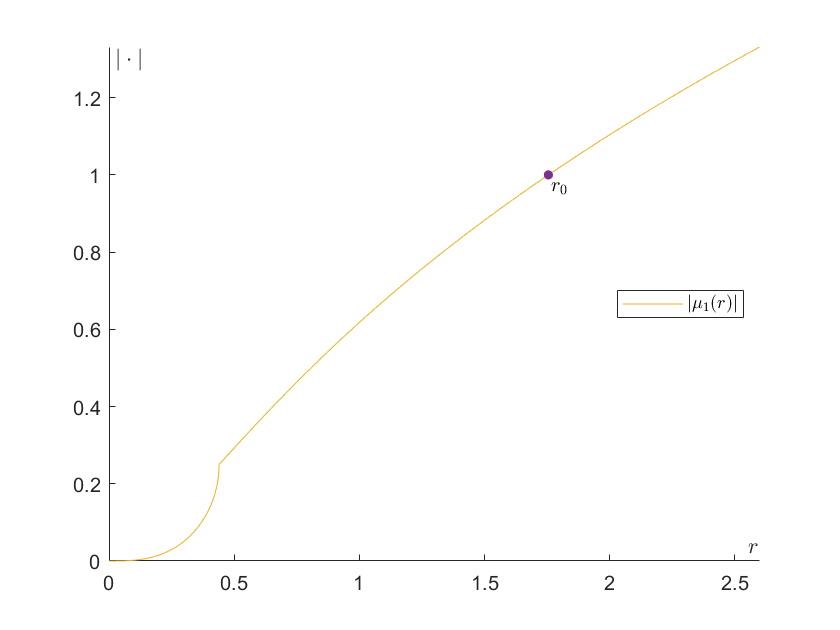

fplot(abs(mu_1),R,'Color','#EDB120'); hold on;
plotstyle1('$r$','$|\cdot|$','$|\mu_1(r)|$','east');
plot(r1_0,1,'Marker','.',"MarkerSize", 16,'Color','#7E2F8E');
text(r1_0+0.01,1-0.03,'$r_0$','Interpreter',"latex");
hold off;
exportgraphics(gcf,'pictures\ds2_mu1_abs.pdf');

Второй мультипликатор

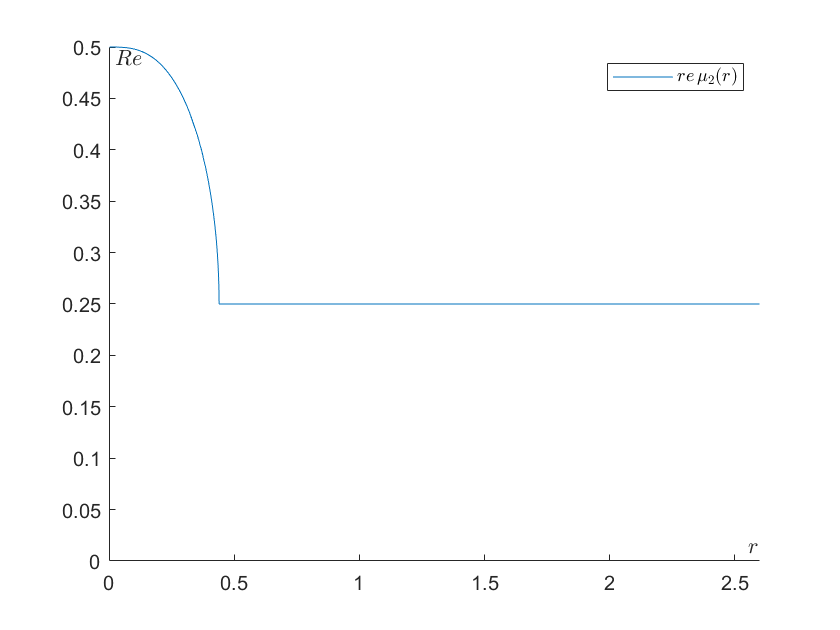

mu_2 = lambda(2);

fplot(real(mu_2),R); hold on;
ax = gca; ax.YLim(1) = 0;
plotstyle1('$r$','$Re$','$re\,\mu_2(r)$','northeast');
hold off;
exportgraphics(gcf,'pictures\ds2_mu2_re.pdf');

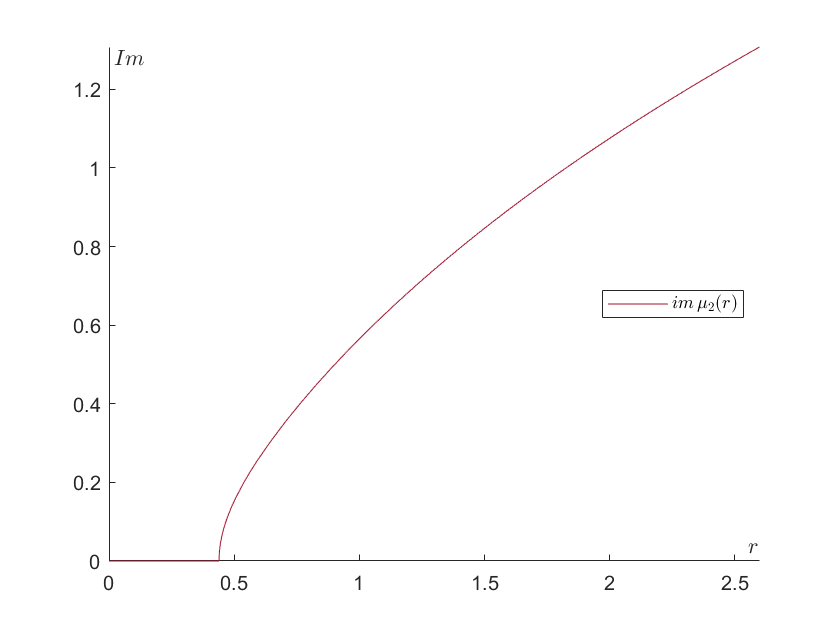


fplot(imag(mu_2),R,'Color','#A2142F'); hold on;
plotstyle1('$r$','$Im$','$ im\,\mu_2(r) $','east');
hold off;
exportgraphics(gcf,'pictures\ds2_mu2_im.pdf');


solve(abs(mu_2)== 1, r) %не решается символьно

$$ans = -1.1572981061383759908250555200048$$

num_mu_2 = matlabFunction(mu_2);
r2_0 = fminbnd(@(r) (abs(num_mu_2(r))-1)^2, 0,r_max) %точка перехода модуля собственного значения через 1 (очевидно то же, что и для 1го (сопряженного данному) собственного значения)

r2_0 = 1.7549

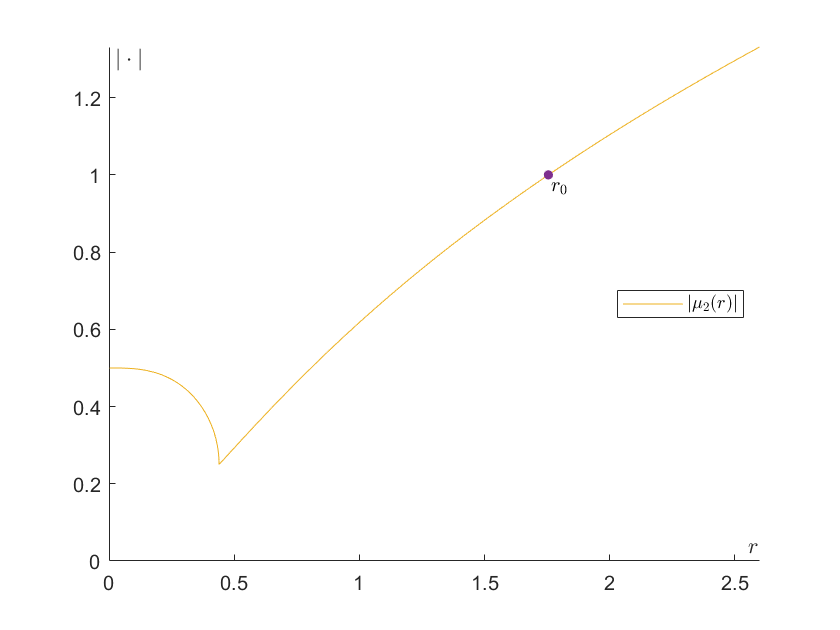

fplot(abs(mu_2),R,'Color','#EDB120'); hold on;
ax = gca; ax.YLim(1) = 0;
plotstyle1('$r$','$|\cdot|$','$|\mu_2(r)|$','east');
plot(r2_0,1,'Marker','.',"MarkerSize", 16,'Color','#7E2F8E');
text(r2_0+0.01,1-0.03,'$r_0$','Interpreter',"latex");
hold off;
exportgraphics(gcf,'pictures\ds2_mu2_abs.pdf');

Бифуркация Неймарка-Сакера (условия невырожденности)

r0 = r2_0

r0 = 1.7549

mu_1 = lambda(1);
vpa(subs(diff(abs(mu_1),r),r,r0))

$$ans = -0.44106668387140510210644703536411-0.11388361352121636481411802856467\,\mathrm{i}$$

theta0 = vpa(angle(subs(mu_1,r,r0)))

$$theta0 = -1.3181146147283507747748111385385$$

k = 1:4;
exp(i*k*theta0)

$$ans = \left(\begin{array}{cccc} 0.25000141066078419907412358652097-0.96824547231970981038197238123025\,\mathrm{i} & -0.87499858933523587322972211992994-0.48412546789168946464050335979068\,\mathrm{i} & -0.68750317398079454514389077952329+0.72618137250024070439303969980445\,\mathrm{i} & 0.53124506267730550645752509260333+0.84721820293297862073604829597284\,\mathrm{i} \end{array}\right)$$

Бифуркация Неймарка-Сакера (иллюстрации)

r0 = 1.7549;
u0 = [0.7 0.7]';
rl0 = r0 - 0.3

rl0 = 1.4549

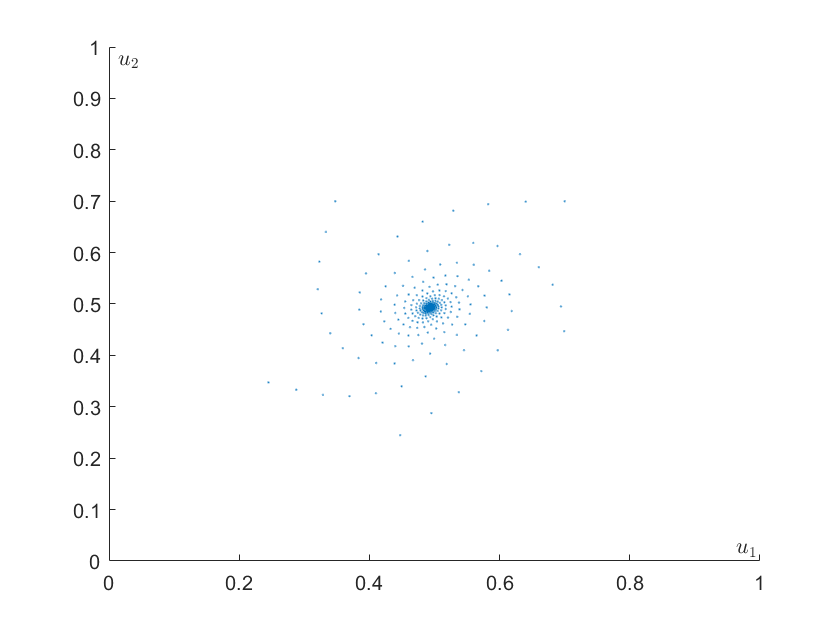

r_point = r0 - 0.37;
r_point_lost = r0 - 0.341;
r_small_curve = r0 - 0.34;
r_med_curve = r0 - 0.33;
r_big_curve = r0 - 0.29;
r_dissipated_curve = r0 - 0.281;

plotNS(r_point,u0,10000);
plotstyle2('$u_1$','$u_2$');
exportgraphics(gcf,'pictures\ds2_NS1.png');

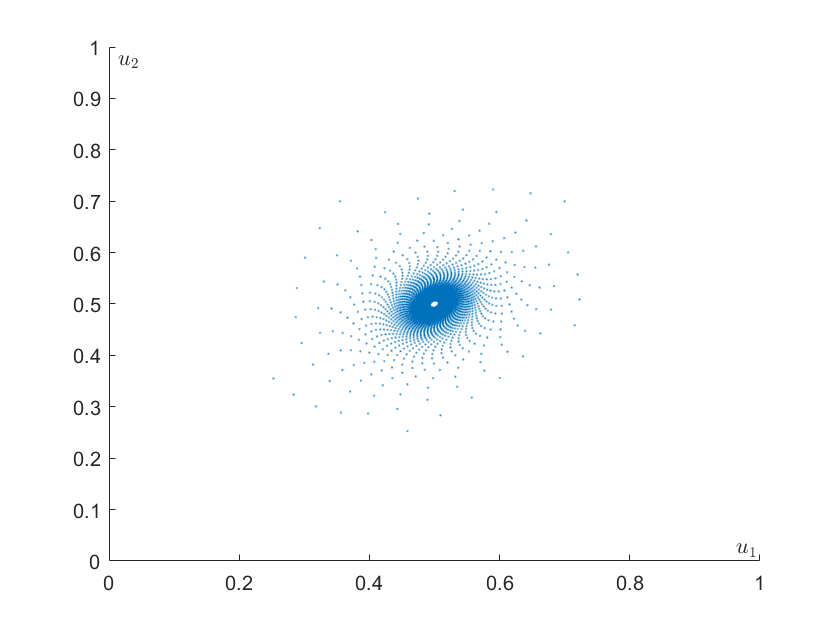


plotNS(r_point_lost,u0,10000);
plotstyle2('$u_1$','$u_2$');
exportgraphics(gcf,'pictures\ds2_NS2.png');

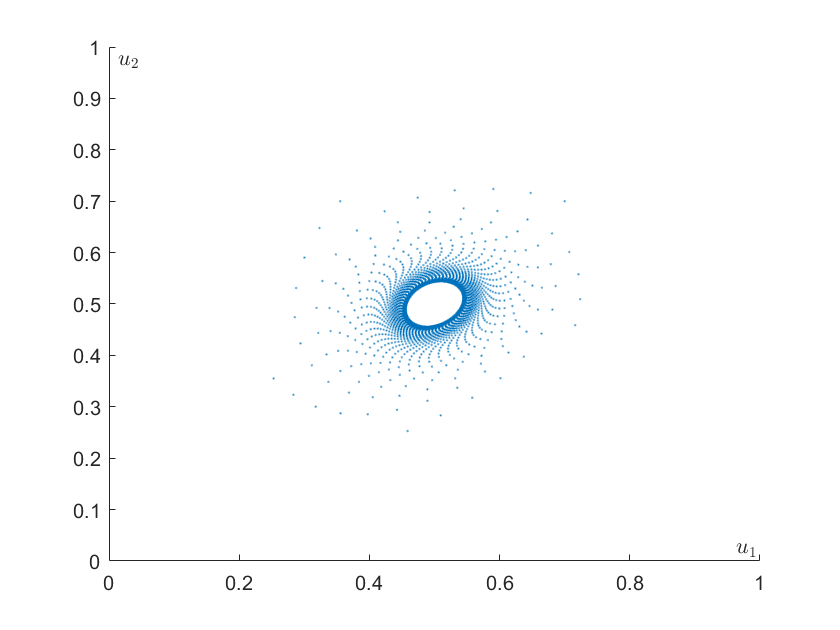


plotNS(r_small_curve,u0,10000);
plotstyle2('$u_1$','$u_2$');
exportgraphics(gcf,'pictures\ds2_NS3.png');

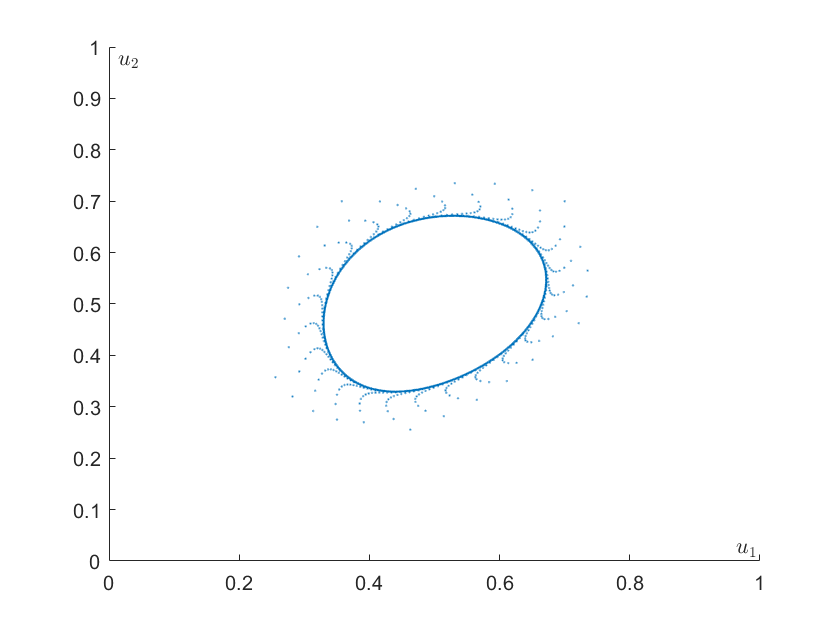


plotNS(r_med_curve,u0,10000);
plotstyle2('$u_1$','$u_2$');
exportgraphics(gcf,'pictures\ds2_NS4.png');

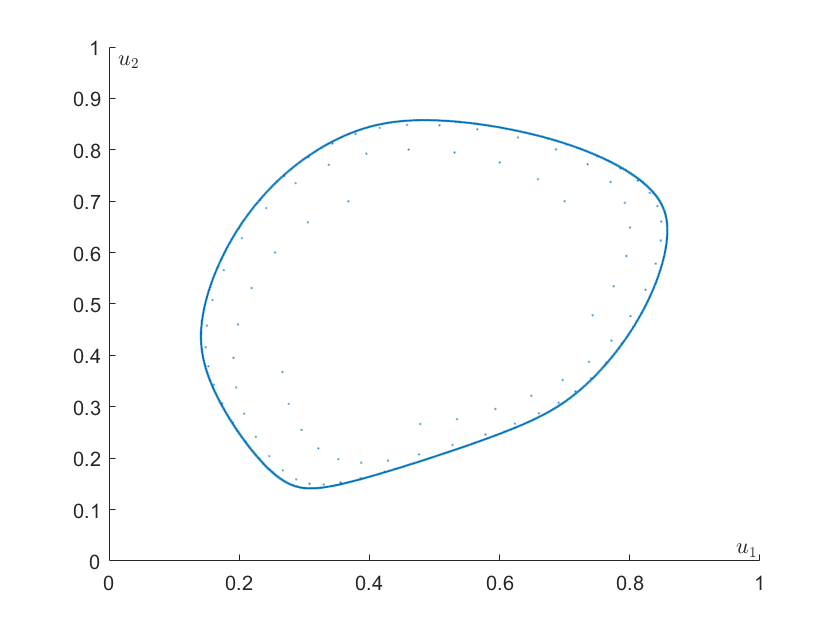


plotNS(r_big_curve,u0,10000);
plotstyle2('$u_1$','$u_2$');
exportgraphics(gcf,'pictures\ds2_NS5.png');

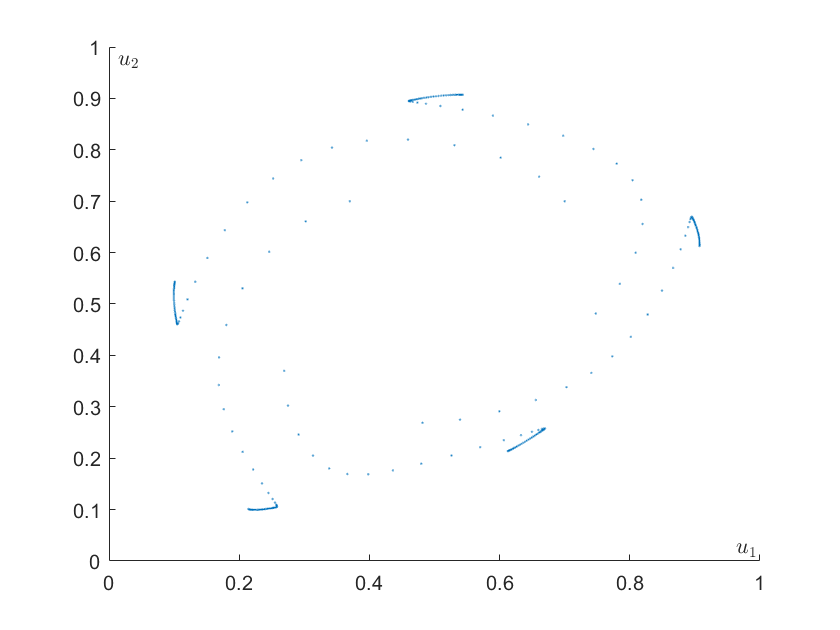


plotNS(r_dissipated_curve,u0,10000);
plotstyle2('$u_1$','$u_2$');
exportgraphics(gcf,'pictures\ds2_NS6.png');

График g(u_1,u_2)

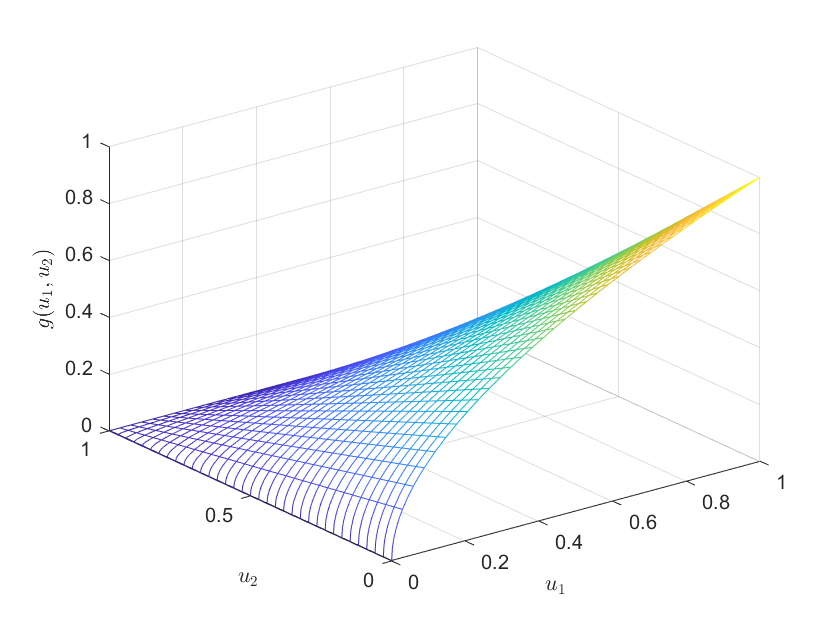

fmesh(@(u1,u2) sqrt(u1).*(1-u2), [0 1])
ax = gca;
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex'; ax.ZLabel.Interpreter = 'latex';
    ax.YLabel.Rotation = 0;
    ax.XLabel.String = '$u_1$'; ax.YLabel.String = '$u_2$'; ax.ZLabel.String = '$g(u_1,u_2)$';
exportgraphics(gcf,'pictures\ds2_g.png');

Вспомогательные функции

function res = ds2(u,r)
    res = [r*sqrt(u(1))*(1-u(2));
            u(1)]; 
end

function U = iterate(ds, times, u0)
    U = zeros(2,times+1);
    U(:,1) = u0;
    
    for it = 1:times
        U(:,it+1) = ds(U(:,it));
    end
end

function plotstyle1(x_label, y_label, line_label, lgd_location)
    ax = gca;
    X = ax.XLim; Y = ax.YLim;
    height = abs(Y(2)-Y(1)); width = abs(X(2)-X(1));
    ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin'; ax.Box = "off";
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.XLabel.Position = [X(2)-width*0.01 Y(1)+height*0.05]; ax.YLabel.Position = [X(1)+width*0.03 Y(2)-height*0.05];
    ax.YLabel.Rotation = 0;
    ax.XLabel.String = x_label; ax.YLabel.String = y_label;
    legend(line_label,'Interpreter','latex','AutoUpdate','off','Location',lgd_location);
end

function plotstyle2(x_label, y_label)
    ax = gca;
    X = ax.XLim; Y = ax.YLim;
    height = abs(Y(2)-Y(1)); width = abs(X(2)-X(1));
    ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin'; ax.Box = "off";
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.XLabel.Position = [X(2)-width*0.02 Y(1)+height*0.05]; ax.YLabel.Position = [X(1)+width*0.03 Y(2)-height*0.05];
    ax.YLabel.Rotation = 0;
    ax.XLabel.String = x_label; ax.YLabel.String = y_label;
end

function plotNS(r,u0,iters)
    f  = @(u) ds2(u,r);
    U = iterate(f,iters,u0);
    plot(U(1,:),U(2,:),'.','MarkerSize', 2,"Color",'#0072BD');
    ax = gca;
    ax.XLim = [0 1]; ax.YLim = [0 1];
end